% load data
load('ad_data.mat');

% adding bias makes no difference as LogisticR() returns w and c it seems
% that it takes care of the bias automatically
% X_train = [ones(size(y_train,1), 1) X_train]
% X_test = [ones(size(y_test,1), 1) X_test]

% checking class distribution of test and train sets
% disp(sum(y_train == -1)/size(y_train,1))
% disp(sum(y_test == -1)/size(y_test,1))

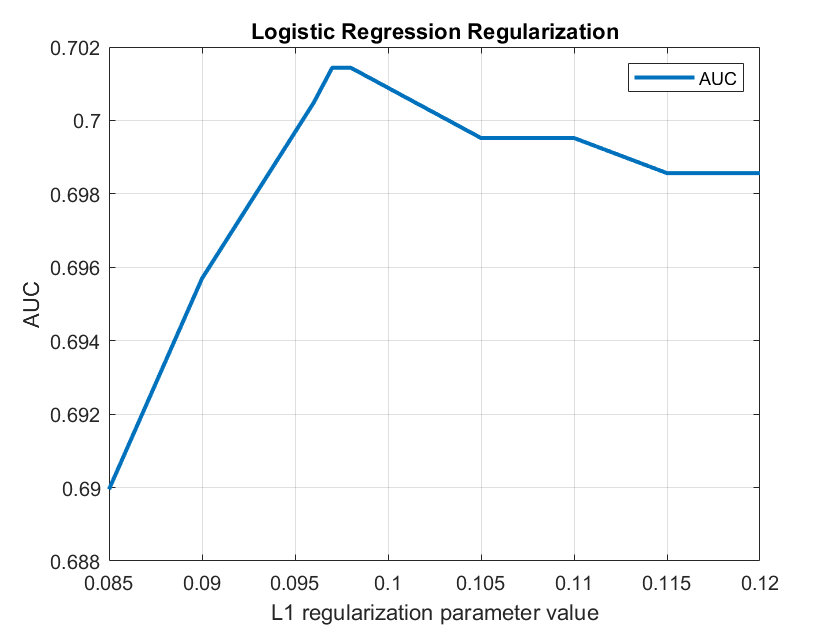

% first set of parameters
% par = [1e-8, 0.01, 0.1, 0.2, 0.3, 0.4, 0.5, 0.6, 0.7, 0.8, 0.9, 1];

% second set of parameters
par  = [0.085, 0.09, 0.096, 0.097, 0.0975, 0.098, 0.105, 0.11, 0.115, 0.12];
accuracy = zeros(size(par));
auc_vals = zeros(size(par));
non_zero = zeros(size(par));
i = 1;
for val = par
    [w, c] = logistic_l1_train(X_train, y_train, val);
    non_zero(i) = sum(w ~= 0);
    % create predictions to obtain accuracy
    predictions = zeros(size(y_test));
    predictions(X_test*w + c < 0) = -1;
    predictions(X_test*w + c >= 0) = 1;
    accuracy(i) = 1 - sum(predictions ~= y_test)/size(y_test,1);
    prediction_values = X_test*w + c;
    [X, Y, ~, AUC] = perfcurve(y_test, prediction_values, 1);
    auc_vals(i) = AUC;
    % plot AUC curves
    figure
    plot(X,Y)
    xlabel('False positive rate') 
    ylabel('True positive rate')
    title('ROC for Classification by Logistic Regression')
    i = i + 1;
end

% plot and save the results
% this was for an all in one plot that did not look very good
% figure
% plot(par, [auc_vals' non_zero'/100 accuracy'],'LineWidth',2)
% grid on 
% xlabel('L1 regularization parameter value') 
% ylabel('AUC') 
% title('Logistic Regression Regularization') 
% legend('AUC', 'Number of Features(x100)', 'Test Accuracy')
% savefig('p2_Logistic_regression_plot.fig')

% plot and save the results
figure
plot(par, auc_vals,'LineWidth',2)
grid on 
xlabel('L1 regularization parameter value') 
ylabel('AUC') 
title('Logistic Regression Regularization') 
legend('AUC')
savefig('p2_Logistic_regression_AUC_plot.fig')

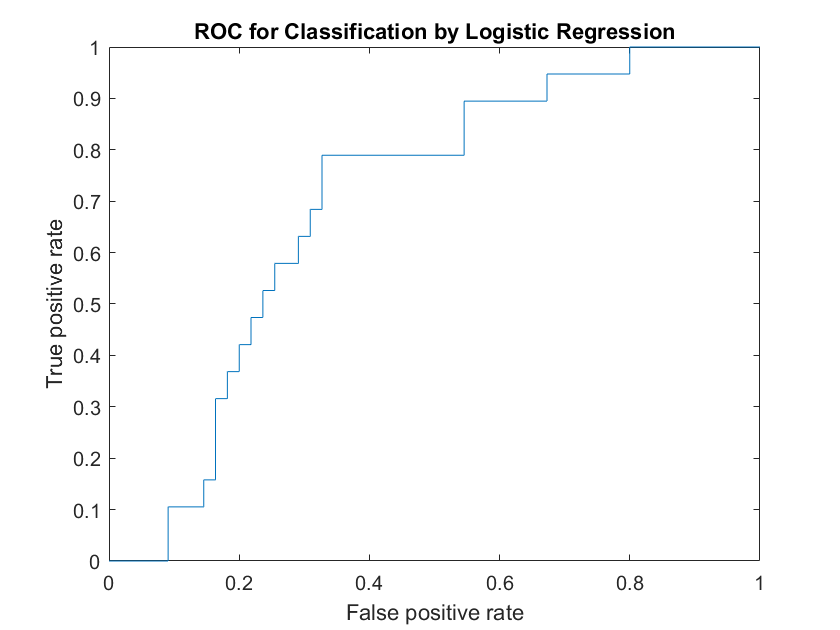

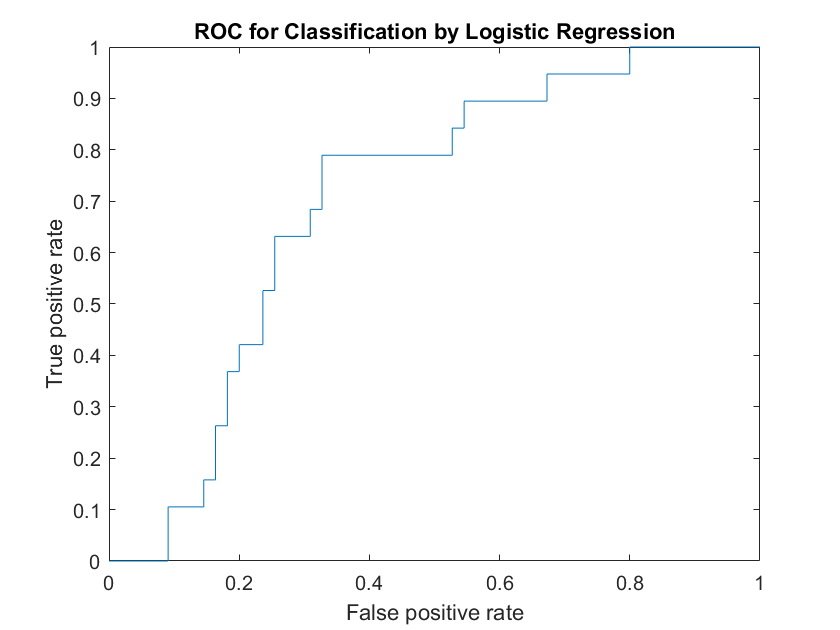

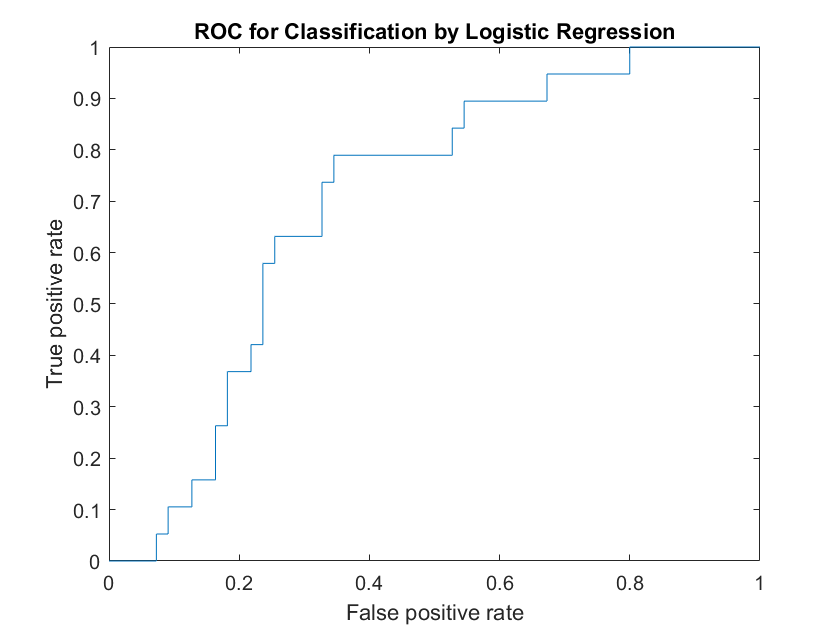

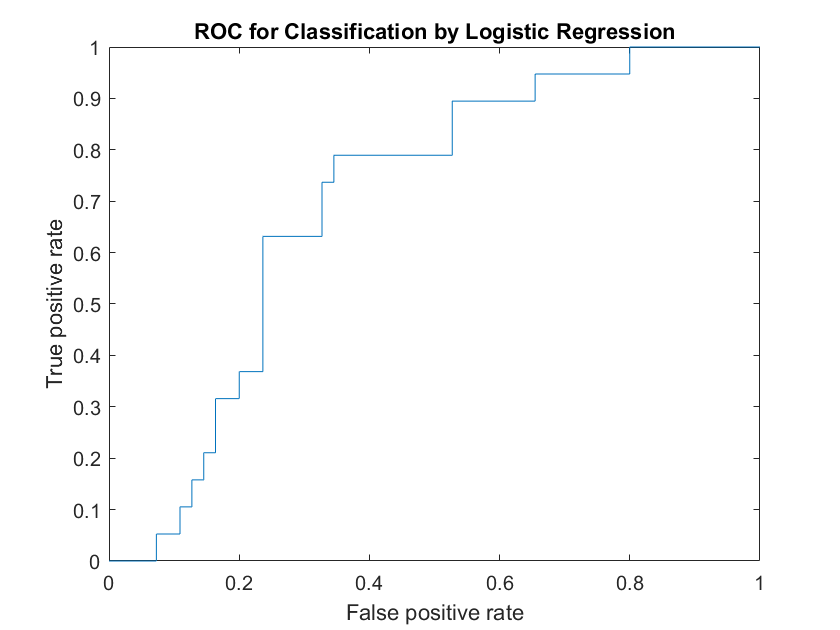

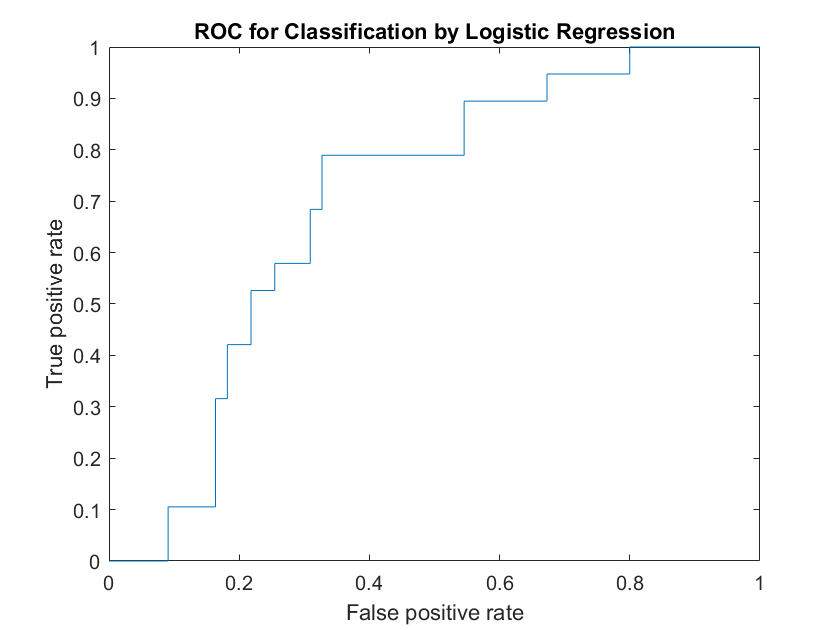

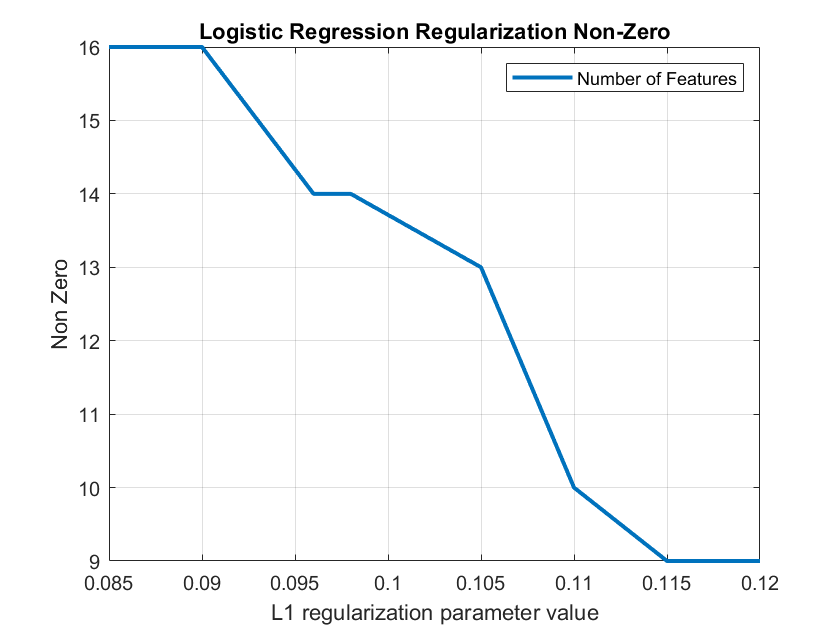


% plot and save the results
figure
plot(par, non_zero,'LineWidth',2)
grid on 
xlabel('L1 regularization parameter value') 
ylabel('Non Zero') 
title('Logistic Regression Regularization Non-Zero') 
legend('Number of Features')
savefig('p2_Logistic_regression_non_zero_plot.fig')

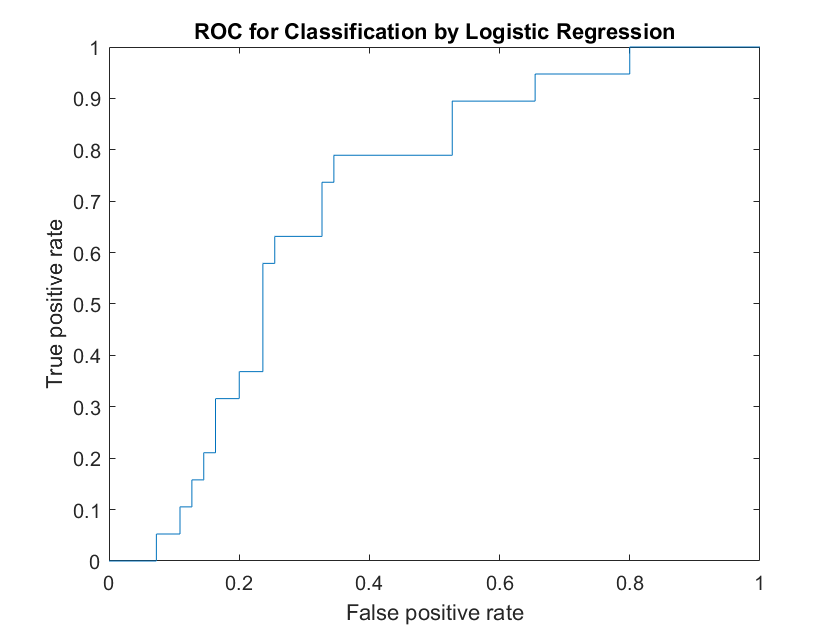

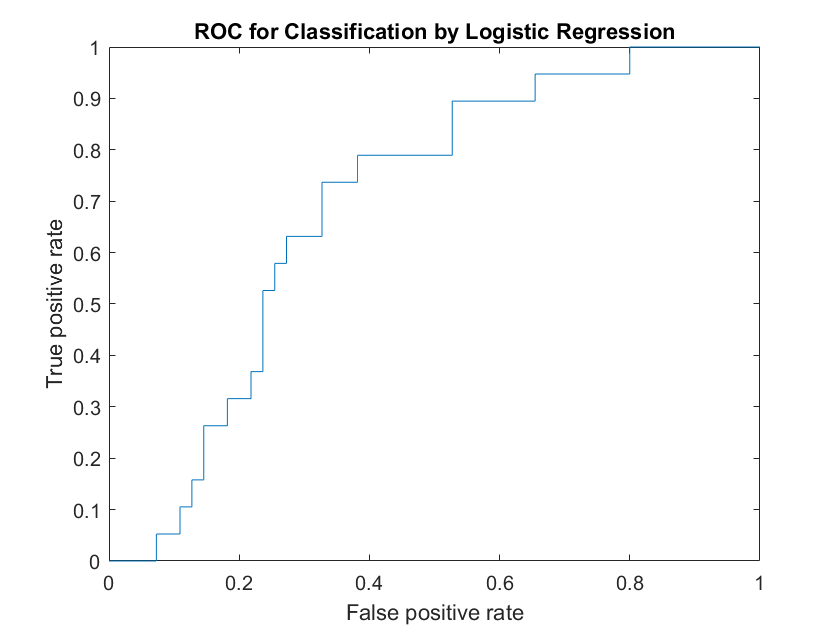

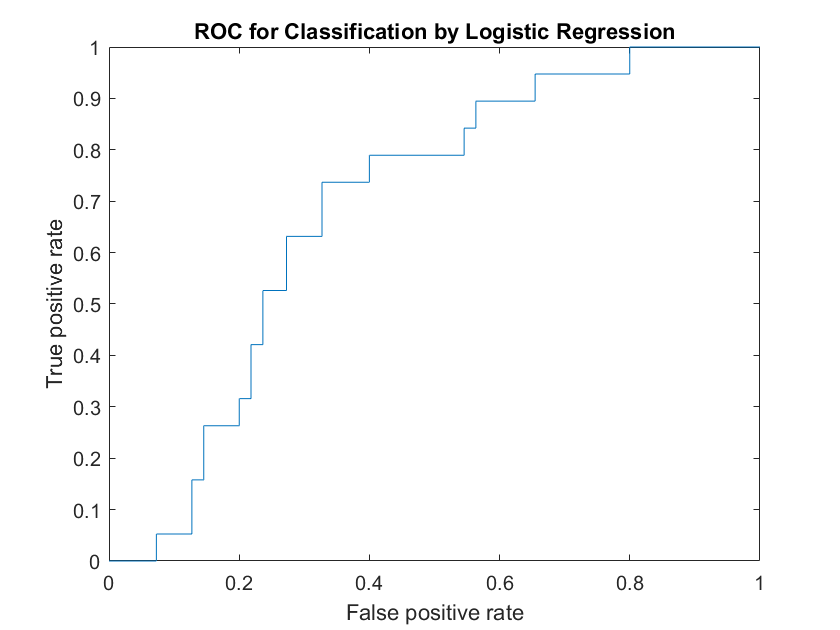

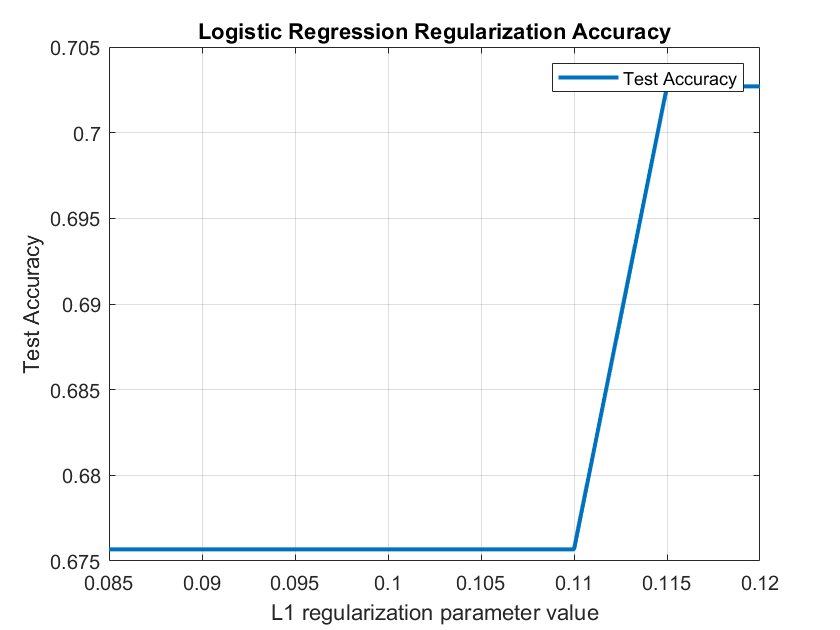


% plot and save the results
figure
plot(par, accuracy,'LineWidth',2)
grid on 
xlabel('L1 regularization parameter value') 
ylabel('Test Accuracy') 
title('Logistic Regression Regularization Accuracy') 
legend('Test Accuracy')
savefig('p2_Logistic_regression_accuracy_plot.fig')

function [w, c] = logistic_l1_train(data, labels, par)
% OUTPUT w is equivalent to the first d dimension of weights in logistic train
% c is the bias term, equivalent to the last dimension in weights in logistic train.
% Specify the options (use without modification).
opts.rFlag = 1; % range of par within [0, 1].
opts.tol = 1e-6; % optimization precision
opts.tFlag = 4; % termination options.
opts.maxIter = 5000; % maximum iterations.
[w, c] = LogisticR(data, labels, par, opts);

function [x, c, funVal, ValueL]=LogisticR(A, y, z, opts)
%
%%
% Function LogisticR
%      Logistic Loss with the L1-norm Regularization
%
%% Problem
%
%  min  f(x,c) = - weight_i * log (p_i) + 1/2 rsL2 * ||x||_2^2
%                 + z * \|x\|_1
%
%  By default, rsL2=0.
%
%  a_i denotes a training sample,
%      and a_i' corresponds to the i-th row of the data matrix A
%
%  y_i (either 1 or -1) is the response
%
%  p_i= 1/ (1+ exp(-y_i (x' * a_i + c) ) ) denotes the probability
%
%  weight_i denotes the weight for the i-th sample
%
%% Input parameters:
%
%  A-         Matrix of size m x n
%                A can be a dense matrix
%                         a sparse matrix
%                         or a DCT matrix
%  y -        Response vector (of size mx1)
%  z -        Lq/L1 norm regularization parameter (z >=0)
%  opts-      Optional inputs (default value: opts=[])
%
%% Output parameters:
%  x-         The obtained weight of size n x 1
%  c-         The obtained intercept (scalar)
%  funVal-    Function value during iterations
%
%% Copyright (C) 2009-2010 Jun Liu, and Jieping Ye
%
% You are suggested to first read the Manual.
%
% For any problem, please contact with Jun Liu via j.liu@asu.edu
%
% Last modified on February 18, 2010.
%
%% Related papers
%
% [1]  Jun Liu, Jianhui Chen, and Jieping Ye, Large-Scale Sparse Logistic
%      Regression, KDD09
%
% [2]  Jun Liu and Jieping Ye, Efficient Euclidean Projections
%      in Linear Time, ICML 2009.
%
%% Related functions
%
%  sll_opts, initFactor, pathSolutionLeast
%  LogisticC, nnLogisticR, nnLogisticC
%
%%

%% Verify and initialize the parameters
%%
if (nargin <3)
    error('\n Inputs: A, y, and z should be specified!\n');
end

[m,n]=size(A);

if (length(y) ~=m)
    error('\n Check the length of y!\n');
end

if (z<=0)
    error('\n z should be positive!\n');
end

opts=sll_opts(opts); % run sll_opts to set default values (flags)

%% Detailed initialization
%% Normalization

% Please refer to sll_opts for the definitions of mu, nu and nFlag
%
% If .nFlag =1, the input matrix A is normalized to
%                     A= ( A- repmat(mu, m,1) ) * diag(nu)^{-1}
%
% If .nFlag =2, the input matrix A is normalized to
%                     A= diag(nu)^{-1} * ( A- repmat(mu, m,1) )
%
% Such normalization is done implicitly
%     This implicit normalization is suggested for the sparse matrix
%                                    but not for the dense matrix
%

if (opts.nFlag~=0)
    if (isfield(opts,'mu'))
        mu=opts.mu;
        if(size(mu,2)~=n)
            error('\n Check the input .mu');
        end
    else
        mu=mean(A,1);
    end

    if (opts.nFlag==1)
        if (isfield(opts,'nu'))
            nu=opts.nu;
            if(size(nu,1)~=n)
                error('\n Check the input .nu!');
            end
        else
            nu=(sum(A.^2,1)/m).^(0.5); nu=nu';
        end
    else % .nFlag=2
        if (isfield(opts,'nu'))
            nu=opts.nu;
            if(size(nu,1)~=m)
                error('\n Check the input .nu!');
            end
        else
            nu=(sum(A.^2,2)/n).^(0.5);
        end
    end

    ind_zero=find(abs(nu)<= 1e-10);    nu(ind_zero)=1;
    % If some values in nu is typically small, it might be that,
    % the entries in a given row or column in A are all close to zero.
    % For numerical stability, we set the corresponding value to 1.
end

if (~issparse(A)) && (opts.nFlag~=0)
    fprintf('\n -----------------------------------------------------');
    fprintf('\n The data is not sparse or not stored in sparse format');
    fprintf('\n The code still works.');
    fprintf('\n But we suggest you to normalize the data directly,');
    fprintf('\n for achieving better efficiency.');
    fprintf('\n -----------------------------------------------------');
end

%% Group & others

% The parameter 'weight' contains the weight for each training sample.
% See the definition of the problem above.
% The summation of the weights for all the samples equals to 1.
if (isfield(opts,'sWeight'))
    sWeight=opts.sWeight;

    if ( length(sWeight)~=2 || sWeight(1) <=0 || sWeight(2) <= 0)
        error('\n Check opts.sWeight, which contains two positive values');
    end

    % we process the weight, so that the summation of the weights for all
    % the samples is 1.

    p_flag=(y==1);                  % the indices of the postive samples
    m1=sum(p_flag) * sWeight(1);    % the total weight for the positive samples
    m2=sum(~p_flag) * sWeight(2);   % the total weight for the positive samples

    weight(p_flag,1)=sWeight(1)/(m1+m2);
    weight(~p_flag,1)=sWeight(2)/(m1+m2);
else
    weight=ones(m,1)/m;             % if not specified, we apply equal weight
end

%% Starting point initialization

% process the regularization parameter

% L2 norm regularization
if isfield(opts,'rsL2')
    rsL2=opts.rsL2;
    if (rsL2<0)
        error('\n opts.rsL2 should be nonnegative!');
    end
else
    rsL2=0;
end

p_flag=(y==1);                  % the indices of the postive samples
m1=sum(weight(p_flag));         % the total weight for the positive samples
m2=1-m1;                        % the total weight for the positive samples

% L1 norm regularization
if (opts.rFlag==0)
    lambda=z;
else % z here is the scaling factor lying in [0,1]
    if (z<0 || z>1)
        error('\n opts.rFlag=1, and z should be in [0,1]');
    end

    % we compute ATb for computing lambda_max, when the input z is a ratio

    b(p_flag,1)=m2;  b(~p_flag,1)=-m1;
    b=b.*weight;

    % compute AT b
    if (opts.nFlag==0)
        ATb =A'*b;
    elseif (opts.nFlag==1)
        ATb= A'*b - sum(b) * mu';  ATb=ATb./nu;
    else
        invNu=b./nu;               ATb=A'*invNu-sum(invNu)*mu';
    end

    lambda_max=max(abs(ATb));
    lambda=z*lambda_max;

    rsL2=rsL2*lambda_max; % the input rsL2 is a ratio of lambda_max
end

% initialize a starting point
if opts.init==2
    x=zeros(n,1); c=log(m1/m2);
else
    if isfield(opts,'x0')
        x=opts.x0;
        if (length(x)~=n)
            error('\n Check the input .x0');
        end
    else
        x=zeros(n,1);
    end

    if isfield(opts,'c0')
        c=opts.c0;
    else
        c=log(m1/m2);
    end
end

% compute A x
if (opts.nFlag==0)
    Ax=A* x;
elseif (opts.nFlag==1)
    invNu=x./nu; mu_invNu=mu * invNu;
    Ax=A*invNu -repmat(mu_invNu, m, 1);
else
    Ax=A*x-repmat(mu*x, m, 1);    Ax=Ax./nu;
end

%% The main program

%% The Armijo Goldstein line search scheme + accelearted gradient descent

if (opts.mFlag==0 && opts.lFlag==0)

    bFlag=0; % this flag tests whether the gradient step only changes a little

    L=1/m + rsL2; % the intial guess of the Lipschitz continuous gradient

    weighty=weight.*y;
    % the product between weight and y

    % assign xp with x, and Axp with Ax
    xp=x; Axp=Ax; xxp=zeros(n,1);
    cp=c;         ccp=0;

    alphap=0; alpha=1;

    for iterStep=1:opts.maxIter
        % --------------------------- step 1 ---------------------------
        % compute search point s based on xp and x (with beta)
        beta=(alphap-1)/alpha;    s=x + beta* xxp;  sc=c + beta* ccp;

        % --------------------------- step 2 ---------------------------
        % line search for L and compute the new approximate solution x

        % compute As=A*s
        As=Ax + beta* (Ax-Axp);

        % aa= - diag(y) * (A * s + sc)
        aa=- y.*(As+ sc);

        % fun_s is the logistic loss at the search point
        bb=max(aa,0);
        fun_s= weight' * ( log( exp(-bb) +  exp(aa-bb) ) + bb )+...
            rsL2/2 * s'*s;

        % compute prob=[p_1;p_2;...;p_m]
        prob=1./( 1+ exp(aa) );

        % b= - diag(y.* weight) * (1 - prob)
        b= -weighty.*(1-prob);

        gc=sum(b); % the gradient of c

        % compute g= AT b, the gradient of x
        if (opts.nFlag==0)
            g=A'*b;
        elseif (opts.nFlag==1)
            g=A'*b - sum(b) * mu';  g=g./nu;
        else
            invNu=b./nu;              g=A'*invNu-sum(invNu)*mu';
        end

        g=g+ rsL2 * s;  % add the squared L2 norm regularization term

        % copy x and Ax to xp and Axp
        xp=x;    Axp=Ax;
        cp=c;

        while (1)
            % let s walk in a step in the antigradient of s to get v
            % and then do the Lq/L1-norm regularized projection
            v=s-g/L;  c= sc- gc/L;

            % L1-norm regularized projection
            x=sign(v).*max(abs(v)-lambda / L,0);

            v=x-s;  % the difference between the new approximate solution x
            % and the search point s

            % compute A x
            if (opts.nFlag==0)
                Ax=A* x;
            elseif (opts.nFlag==1)
                invNu=x./nu; mu_invNu=mu * invNu;
                Ax=A*invNu -repmat(mu_invNu, m, 1);
            else
                Ax=A*x-repmat(mu*x, m, 1);     Ax=Ax./nu;
            end

            % aa= - diag(y) * (A * x + c)
            aa=- y.*(Ax+ c);

            % fun_x is the logistic loss at the new approximate solution
            bb=max(aa,0);
            fun_x= weight'* ( log( exp(-bb) +  exp(aa-bb) ) + bb ) +...
                rsL2/2 * x'*x;

            r_sum= (v'*v + (c-sc)^2) / 2;
            l_sum=fun_x - fun_s - v'* g - (c-sc)* gc;

            if (r_sum <=1e-20)
                bFlag=1; % this shows that, the gradient step makes little improvement
                break;
            end

            % the condition is fun_x <= fun_s + v'* g + c * gc
            %                           + L/2 * (v'*v + (c-sc)^2 )
            if(l_sum <= r_sum * L)
                break;
            else
                L=max(2*L, l_sum/r_sum);
                %fprintf('\n L=%e, r_sum=%e',L, r_sum);
            end
        end

        % --------------------------- step 3 ---------------------------
        % update alpha and alphap, and check whether converge
        alphap=alpha; alpha= (1+ sqrt(4*alpha*alpha +1))/2;

        ValueL(iterStep)=L;
        % store values for L
        
        xxp=x-xp;    ccp=c-cp;
        funVal(iterStep)=fun_x + lambda* sum(abs(x));

        if (bFlag)
            % fprintf('\n The program terminates as the gradient step changes the solution very small.');
            break;
        end

        switch(opts.tFlag)
            case 0
                if iterStep>=2
                    if (abs( funVal(iterStep) - funVal(iterStep-1) ) <= opts.tol)
                        break;
                    end
                end
            case 1
                if iterStep>=2
                    if (abs( funVal(iterStep) - funVal(iterStep-1) ) <=...
                            opts.tol* funVal(iterStep-1))
                        break;
                    end
                end
            case 2
                if ( funVal(iterStep)<= opts.tol)
                    break;
                end
            case 3
                norm_xxp=sqrt(xxp'*xxp);
                if ( norm_xxp <=opts.tol)
                    break;
                end
            case 4
                norm_xp=sqrt(xp'*xp);    norm_xxp=sqrt(xxp'*xxp);
                if ( norm_xxp <=opts.tol * max(norm_xp,1))
                    break;
                end
            case 5
                if iterStep>=opts.maxIter
                    break;
                end
        end
    end
end


%% Reformulated problem + Nemirovski's line search scheme

% Original problem:           min  f(x,c) = - weight_i * log (p_i) + 1/2 rsL2 * ||x||_2^2
%                                                      + z * \|x\|_1
%
% Reformulated problem:   min  f(x,c) = - weight_i * log (p_i) + 1/2 rsL2 * ||x||_2^2
%                                                      + z * 1^T t
%                                   s.t., |x| <=t

if (opts.mFlag==1 && opts.lFlag==0)

    bFlag=0; % this flag tests whether the gradient step only changes a little

    L=1/m + rsL2; % the intial guess of the Lipschitz continuous gradient

    weighty=weight.*y;
    % the product between weight and y

    % assign xp with x, and Axp with Ax
    xp=x;         Axp=Ax;     xxp=zeros(n,1);
    cp=c;         ccp=0;

    t=abs(x); tp=t;
    % t is the upper bound of absolute value of x

    alphap=0; alpha=1;

    for iterStep=1:opts.maxIter
        % --------------------------- step 1 ---------------------------
        % compute search point s based on xp and x (with beta)
        beta=(alphap-1)/alpha;    s=x + beta* xxp;  sc=c + beta* ccp; s_t= t + beta * (t -tp);

        % --------------------------- step 2 ---------------------------
        % line search for L and compute the new approximate solution x

        % compute As=A*s
        As=Ax + beta* (Ax-Axp);

        % aa= - diag(y) * (A * s + sc)
        aa=- y.*(As+ sc);

        % fun_s is the logistic loss at the search point
        bb=max(aa,0);
        fun_s= weight' * ( log( exp(-bb) +  exp(aa-bb) ) + bb )+...
            rsL2/2 * s'*s;

        % compute prob=[p_1;p_2;...;p_m]
        prob=1./( 1+ exp(aa) );

        % b= - diag(y.* weight) * (1 - prob)
        b= -weighty.*(1-prob);

        gc=sum(b); % the gradient of c

        % compute g= AT b, the gradient of x
        if (opts.nFlag==0)
            g=A'*b;
        elseif (opts.nFlag==1)
            g=A'*b - sum(b) * mu';  g=g./nu;
        else
            invNu=b./nu;              g=A'*invNu-sum(invNu)*mu';
        end

        g=g+ rsL2 * s;  % add the squared L2 norm regularization term

        % copy x and Ax to xp and Axp
        xp=x;    Axp=Ax;
        cp=c;    tp=t;

        while (1)
            % let s walk in a step in the antigradient of s to get v
            % and then do the Lq/L1-norm regularized projection
            c= sc- gc/L;
            u=s-g/L;
            v= s_t - lambda / L;

            % projection
            [x, t]=ep1R(u,v,n);

            v=x-s;  % the difference between the new approximate solution x
            % and the search point s
            v_t=t-s_t;

            % compute A x
            if (opts.nFlag==0)
                Ax=A* x;
            elseif (opts.nFlag==1)
                invNu=x./nu; mu_invNu=mu * invNu;
                Ax=A*invNu -repmat(mu_invNu, m, 1);
            else
                Ax=A*x-repmat(mu*x, m, 1);     Ax=Ax./nu;
            end

            % aa= - diag(y) * (A * x + c)
            aa=- y.*(Ax+ c);

            % fun_x is the logistic loss at the new approximate solution
            bb=max(aa,0);
            fun_x= weight'* ( log( exp(-bb) +  exp(aa-bb) ) + bb ) +...
                rsL2/2 * x'*x;

            r_sum= (v'*v + (c-sc)^2 + v_t'*v_t) / 2;
            l_sum=fun_x - fun_s - v'* g - (c-sc)* gc;

            if (r_sum <=1e-20)
                bFlag=1; % this shows that, the gradient step makes little improvement
                break;
            end

            % the condition is fun_x <= fun_s + v'* g + c * gc
            %                           + L/2 * (v'*v + (c-sc)^2 )
            if(l_sum <= r_sum * L)
                break;
            else
                L=max(2*L, l_sum/r_sum);
                %fprintf('\n L=%e, r_sum=%e',L, r_sum);
            end
        end

        % --------------------------- step 3 ---------------------------
        % update alpha and alphap, and check whether converge
        alphap=alpha; alpha= (1+ sqrt(4*alpha*alpha +1))/2;
        
        ValueL(iterStep)=L;
        % store values for L
        
        xxp=x-xp;    ccp=c-cp;
        funVal(iterStep)=fun_x + lambda* sum(t);

        if (bFlag)
            % fprintf('\n The program terminates as the gradient step changes the solution very small.');
            break;
        end

        switch(opts.tFlag)
            case 0
                if iterStep>=2
                    if (abs( funVal(iterStep) - funVal(iterStep-1) ) <= opts.tol)
                        break;
                    end
                end
            case 1
                if iterStep>=2
                    if (abs( funVal(iterStep) - funVal(iterStep-1) ) <=...
                            opts.tol* funVal(iterStep-1))
                        break;
                    end
                end
            case 2
                if ( funVal(iterStep)<= opts.tol)
                    break;
                end
            case 3
                norm_xxp=sqrt(xxp'*xxp + norm(t-tp)^2 + (c-cp)^2);
                if ( norm_xxp <=opts.tol)
                    break;
                end
            case 4
                norm_xp=sqrt(xp'*xp + cp^2 + tp'*tp);    norm_xxp=sqrt(xxp'*xxp + norm(t-tp)^2 + (c-cp)^2);
                if ( norm_xxp <=opts.tol * max(norm_xp,1))
                    break;
                end
            case 5
                if iterStep>=opts.maxIter
                    break;
                end
        end
    end
end


%% Reformulated problem + adaptive line search scheme

% Original problem:           min  f(x,c) = - weight_i * log (p_i) + 1/2 rsL2 * ||x||_2^2
%                                                      + z * \|x\|_1
%
% Reformulated problem:   min  f(x,c) = - weight_i * log (p_i) + 1/2 rsL2 * ||x||_2^2
%                                                      + z * 1^T t
%                                   s.t., |x| <=t

if (opts.mFlag==1 && opts.lFlag==1)

    bFlag=0; % this flag tests whether the gradient step only changes a little

    L=1/m + rsL2; % the intial guess of the Lipschitz continuous gradient

    weighty=weight.*y;
    % the product between weight and y

    gamma=1;
    % we shall set the value of gamma = L,
    % and L is appropriate for the starting point

    % assign xp with x, and Axp with Ax
    xp=x; Axp=Ax; xxp=zeros(n,1);
    cp=c;         ccp=0;
    t=abs(x); tp=t;
    % t is the upper bound of absolute value of x

    for iterStep=1:opts.maxIter
        while (1)
            if (iterStep~=1)
                alpha= (-gamma+ sqrt(gamma*gamma + 4* L * gamma)) / (2*L);
                beta= (gamma - gamma* alphap) / (alphap * gamma + alphap* L * alpha);
                % beta is the coefficient for generating search point s

                s=x + beta* xxp;   s_t= t + beta * (t -tp); sc=c + beta* ccp;
                As=Ax + beta* (Ax-Axp);
            else
                alpha= (-1+ sqrt(5)) / 2;  beta=0;
                s=x; s_t=t; sc= c;
                As=Ax;
            end

            % aa= - diag(y) * (A * s + sc)
            aa=- y.*(As+ sc);

            % fun_s is the logistic loss at the search point
            bb=max(aa,0);
            fun_s= weight' * ( log( exp(-bb) +  exp(aa-bb) ) + bb )+...
                rsL2/2 * s'*s;

            % compute prob=[p_1;p_2;...;p_m]
            prob=1./( 1+ exp(aa) );

            % b= - diag(y.* weight) * (1 - prob)
            b= -weighty.*(1-prob);

            gc=sum(b); % the gradient of c

            % compute g= AT b, the gradient of x
            if (opts.nFlag==0)
                g=A'*b;
            elseif (opts.nFlag==1)
                g=A'*b - sum(b) * mu';  g=g./nu;
            else
                invNu=b./nu;              g=A'*invNu-sum(invNu)*mu';
            end

            g=g+ rsL2 * s;  % add the squared L2 norm regularization term

            % let s walk in a step in the antigradient of s to get v
            % and then do the Lq/L1-norm regularized projection
            cnew= sc- gc/L;   
            u=s-g/L; 
            v= s_t - lambda / L;

            % projection
            [xnew, tnew]=ep1R(u,v,n);

            v=xnew-s;  % the difference between the new approximate solution x
            % and the search point s
            v_t=tnew-s_t;

            % compute A xnew
            if (opts.nFlag==0)
                Axnew=A* xnew;
            elseif (opts.nFlag==1)
                invNu=xnew./nu; mu_invNu=mu * invNu;
                Axnew=A*invNu -repmat(mu_invNu, m, 1);
            else
                Axnew=A*xnew-repmat(mu*xnew, m, 1);     Axnew=Axnew./nu;
            end

            % aa= - diag(y) * (A * x + c)
            aa=- y.*(Axnew+ cnew);

            % fun_x is the logistic loss at the new approximate solution
            bb=max(aa,0);
            fun_x= weight'* ( log( exp(-bb) +  exp(aa-bb) ) + bb ) +...
                rsL2/2 * xnew'*xnew;

            r_sum= (v'*v + (cnew-sc)^2 + v_t'*v_t) / 2;
            l_sum=fun_x - fun_s - v'* g - (cnew-sc)* gc;

            if (r_sum <=1e-20)
                bFlag=1; % this shows that, the gradient step makes little improvement
                break;
            end

            % the condition is fun_x <= fun_s + v'* g + c * gc
            %                           + L/2 * (v'*v + (c-sc)^2 )
            if(l_sum <= r_sum * L)
                break;
            else
                L=max(2*L, l_sum/r_sum);
                %fprintf('\n L=%e, r_sum=%e',L, r_sum);
            end
        end

        gamma=L* alpha* alpha;    alphap=alpha;
        % update gamma, and alphap

        ValueL(iterStep)=L;
        % store values for L

        tao=L * r_sum / l_sum;
        if (tao >=5)
            L=L*0.8;
        end
        % decrease the value of L

        xp=x;  x=xnew; xxp=x-xp;
        Axp=Ax; Ax=Axnew;
        tp=t; t=tnew; 
        cp=c; c=cnew; ccp=c-cp;
        % update x, t, c, and Ax

        funVal(iterStep)=fun_x + lambda* sum(t);

        if (bFlag)
            % fprintf('\n The program terminates as the gradient step changes the solution very small.');
            break;
        end

        switch(opts.tFlag)
            case 0
                if iterStep>=2
                    if (abs( funVal(iterStep) - funVal(iterStep-1) ) <= opts.tol)
                        break;
                    end
                end
            case 1
                if iterStep>=2
                    if (abs( funVal(iterStep) - funVal(iterStep-1) ) <=...
                            opts.tol* funVal(iterStep-1))
                        break;
                    end
                end
            case 2
                if ( funVal(iterStep)<= opts.tol)
                    break;
                end
            case 3
                norm_xxp=sqrt(xxp'*xxp + norm(t-tp)^2 + (c-cp)^2);
                if ( norm_xxp <=opts.tol)
                    break;
                end
            case 4
                norm_xp=sqrt(xp'*xp + cp^2 + tp'*tp);    norm_xxp=sqrt(xxp'*xxp + norm(t-tp)^2 + (c-cp)^2);
                if ( norm_xxp <=opts.tol * max(norm_xp,1))
                    break;
                end
            case 5
                if iterStep>=opts.maxIter
                    break;
                end
        end
    end
end

%%
if(opts.mFlag==0 && opts.lFlag==1)
    error('\n The function does not support opts.mFlag=0 & opts.lFlag=1!');
end
end

end